% Reset
close all;
clear all;

%%%%%%%%%%               User configurations               %%%%%%%%%%
axesColor = 'Black';
% Set default plot limits
xlimCfg = [-500, 500];
ylimCfg = xlimCfg;
zlimCfg = xlimCfg;
% Set axes labels
xlab = 'i';
ylab = 'j';
zlab = 'k';
aspect = [1, 1, 1];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Ejercicio 1.11 Lámpara asimétrica modificada

Suponga que se desea eliminar la sujeción fija entre la lámpara y el techo y se desea reemplazar esta sujeción por una cadena de manera que la lámpara seaa colgante. Además el nuevo diseño deberá contener 6 esferas de iluminación de distintos tamaños, siendo los pesos de las mismas 300, 315, 340 350, 370 y 400 gramos. Las esferas se ordenarán de manera creciente alrededor de los brazos de la lámpara. 

Realice los calculos vectoriales para rediseñar la lámpara de manera que la esfera de iluminación más pequeña corresponda al brazo más **grande** de la lámpara con una longitud de 350 mm. La lampara deberá estar en equilibrio y no ladearse hacia ningún lado.

### Cálculo vectorial

Aún cuando los pesos de las esferas son diferentes, siguen estando en el mismo plano (al igual que el ejercicio anterior).  Por ello también se considerará que $z=0$. Por otro lado, aunque el soporte ya no es fijo y se reemplaza por una cadena, basta con que el centro de masa esté en el punto de anclaje a la cadena. or lo tanto, se resolverá el problema en $\Re^2$ al igual que el anterior.

Se tomarán las siguientes consideraciones:

- Medidas de los brazos y pesos:

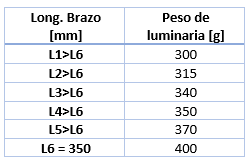

- Se considerará la unión de la cadena cómo el origen (0,0), de donde saldrán todos los brazos.

- Los 6 segmentos estránn distribuidos equitativamente en un círculo. Por lo tanto, la distancia entre cada uno, será:

        
$$\frac{360°}{6}=60°$$


#### Brazo 3

Sea el brazo 3 el vector $v$ y el brazo 6 el vector $w$, ambos en $j=0$

$v=\left\lbrack \begin{array}{c}
i_3 \\
0
\end{array}\right\rbrack$           y          $w\;=\left\lbrack \begin{array}{c}
350\\
0
\end{array}\right\rbrack$

Para que el brazo 2 y 6 estén equilibrados, el centro de masa deberá estar en las coordenadas (0,0). 


$${\mathrm{COM}}_x =\frac{m_1 x_1 +m_2 x_2 +\cdots m_n x_n }{m_1 +m_2 +\cdots +m_n }=0$$



$${\textrm{COM}}_y =\frac{m_1 y_1 +m_2 y_2 +\cdots m_n y_n }{m_1 +m_2 +\cdots +m_n }=0$$


Sustituyendo y despejando para $i_3$y $j_3$


$${\textrm{COM}}_i =\frac{400\left(350\right)+340\left(i_3 \right)}{400+340}=\frac{140,000+340\left(i_3 \right)}{740}$$



$$i_3 =-\frac{140,000}{340}=-411\ldotp 7647$$



$${\mathrm{COM}}_j =\frac{400\left(0\right)+340\left(0\right)}{400+340}=0$$


i_3 = -140000/340;
j_3 = 0;
fact = (-i_3-350)/3;
norm_L4 = -i_3 - fact;
norm_L3 = -i_3;

Por lo tanto


$$v=\left\lbrack \begin{array}{c}
-411\ldotp 7647\\
0
\end{array}\right\rbrack$$


Obteniendo $\parallel v\parallel$ para verificar que $\parallel v\parallel >350$


$$\parallel v\parallel =\sqrt{{\left(-411\ldotp 7647\right)}^2 }=$$

$$411\ldotp 7647$$



$$411\ldotp 7647>350$$
 

Tomando en cuenta que hay 2 brazos entre el brazo 3 y 6, podemos obtener el factor de incremento en $\parallel L\parallel$


$$\frac{\parallel v\parallel -\parallel w\parallel }{3}=\frac{411\ldotp 7647-350}{3}=20\ldotp 5882$$


#### Brazo 4 y 1

Sea el brazo 4 el vector $v$ y el brazo 3 el vector $w$:

$v=\left\lbrack \begin{array}{c}
i_4 \\
j_4 
\end{array}\right\rbrack$           y          $w\;=\left\lbrack \begin{array}{c}
-411\ldotp 7647\\
0
\end{array}\right\rbrack$

 Utilizando el factor anterior podemos obtener $\parallel v\parallel$:


$$\parallel v\parallel =$$

$$\parallel L_3 \parallel -\;20\ldotp 5882$$



$$\parallel v\parallel =411\ldotp 7647-20\ldotp 5882=391\ldotp 1765$$


Utilizando la representación geométrica del producto punto con el ángulo


$$v\cdot w\;=\;\parallel v\parallel \cdot \parallel w\parallel \cos \theta$$


Sustituyendo $v$ y $w$


$$\cos \left(60°\right)=\frac{\left\lbrack \begin{array}{c}
i_4 \\
j_4 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
-411\ldotp 7647\\
0
\end{array}\right\rbrack }{\left(391\ldotp 1765\right)\left(411\ldotp 7647\right)}$$



$$0\ldotp 5=\frac{-411\ldotp 7647\;i_4 }{161,072\ldotp 6742}$$


i_4 = ((norm_L4*norm_L3)*.5)/i_3;


$$i_4 =-195\ldotp 5882$$


Utilizando $\parallel v\parallel$ para calcuar $j_4$


$$\parallel v\parallel =\sqrt{{\left(-195\ldotp 5882\right)}^2 +{j_4 }^2 }=391\ldotp 1765$$



$$j_4 =\sqrt{{{\left(391\ldotp 1765\right)}^2 -\left(-195\ldotp 5882\right)}^2 }=338\ldotp 7688$$


j_4 = sqrt(norm_L4.^2-i_4.^2);

Comprobando que  $\parallel \mathrm{L3}\parallel >\parallel v\parallel >\parallel \mathrm{L6}\parallel$

    
$$411\ldotp 7647>391\ldotp 1765>350$$


Para el cáculo del brazo 1. Se considera que el centro de masa deberá estar en el origen  si el brazo 1 y el brazo 4 son opuestos y forman una linea. Por lo tanto


$${\mathrm{COM}}_i =\frac{{350i}_4 +300i_1 }{350+300}=0$$



$$i_1 =-\frac{350}{300}i_4$$



$$i_1 =-\frac{7}{6}\left(-195\ldotp 5882\right)=228\ldotp 1863$$



$${\mathrm{COM}}_j =\frac{{350j}_4 +300j_1 }{350+300}=0$$



$$j_1 =-\frac{350}{300}j_4$$



$$j_1 =-\frac{7}{6}\left(338\ldotp 7688\right)=-395\ldotp 2302$$


Comprobando que  $\parallel v\parallel >\parallel \mathrm{L3}\parallel >\parallel \mathrm{L4}\parallel >\parallel \mathrm{L6}\parallel$


$$\parallel v\parallel =\sqrt{{\left(-395\ldotp 2302\right)}^2 +{228\ldotp 1863}^2 }=456\ldotp 3725$$


    
$$456\ldotp 3725>411\ldotp 7647>391\ldotp 1765>350$$


i_1 = (-7/6)*i_4;
j_1 = (-7/6)*j_4;
i_6 = 350;
j_6 = 0;

#### Brazo 2 y 5

Sea el brazo 5 el vector $v$ y el brazo 6 el vector $w$:

$v=\left\lbrack \begin{array}{c}
i_3 \\
j_3 
\end{array}\right\rbrack$           y          $w\;=\left\lbrack \begin{array}{c}
350\\
0
\end{array}\right\rbrack$

 Utilizando el factor anterior podemos obtener $\parallel v\parallel$:


$$\parallel v\parallel =$$

$$\parallel w\parallel +\;20\ldotp 5882$$



$$\parallel v\parallel =350+20\ldotp 5882=370\ldotp 5882$$


norm_L6 = 350;
norm_L5 = norm_L6 + fact;

Utilizando la representación geométrica del producto punto con el ángulo


$$v\cdot w\;=\;\parallel v\parallel \cdot \parallel w\parallel \cos \theta$$


Sustituyendo $v$ y $w$


$$\mathrm{cos}\left(60°\right)=\frac{\left\lbrack \begin{array}{c}
i_5 \\
j_5 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
350\\
0
\end{array}\right\rbrack }{\left(370\ldotp 5882\right)\left(350\right)}$$



$$0\ldotp 5=\frac{350\;i_5 }{179,705\ldotp 8823}$$


i_5 = ((norm_L6*norm_L5)*.5)/i_6;


$$i_5 =185\ldotp 2941$$


Utilizando $\parallel v\parallel$ para calcuar $j_5$


$$\parallel v\parallel =\sqrt{{\left(185\ldotp 2941\right)}^2 +{j_5 }^2 }=370\ldotp 5882$$



$$j_5 =\sqrt{{{\left(370\ldotp 5882\right)}^2 -\left(185\ldotp 2941\right)}^2 }=320\ldotp 9316$$


Comprobando que  $\parallel \mathrm{L1}\parallel >\parallel \mathrm{L3}\parallel >\parallel \mathrm{L4}\parallel >\parallel v\parallel >\parallel \mathrm{L6}\parallel$

    
$$456\ldotp 3725>411\ldotp 7647>391\ldotp 1765>370\ldotp 5882>350$$


j_5 = sqrt(norm_L5.^2-i_5.^2);

Para el cáculo del brazo 2. Se considera que el centro de masa deberá estar en el origen  si el brazo 2 y el brazo 5 son opuestos y forman una linea. Por lo tanto


$${\mathrm{COM}}_i =\frac{{315i}_2 +370i_5 }{315+370}=0$$



$$i_2 =-\frac{370}{315}i_5$$



$$i_2 =-\frac{74}{63}\left(185\ldotp 2941\right)=-217\ldotp 64$$
 


$${\mathrm{COM}}_j =\frac{{315j}_2 +370j_5 }{315+370}=0$$



$$j_2 =-\frac{370}{315}j_4$$



$$j_2 =-\frac{74}{63}\left(320\ldotp 9316\right)=-376\ldotp 96$$


#### Comprobando que  $\parallel \mathrm{L1}\parallel >v>\parallel \mathrm{L3}\parallel >\parallel \mathrm{L4}\parallel >\parallel \mathrm{L5}\parallel >\parallel \mathrm{L6}\parallel$


$$\parallel v\parallel =\sqrt{{\left(-273\ldotp 2317\right)}^2 +{\left(-157\ldotp 7503\right)}^2 }=435\ldotp 2941$$


    
$$456\ldotp 3725>435\ldotp 2941>411\ldotp 7647>391\ldotp 1765>370\ldotp 5882>350$$


#### Comprobando que el centro de masa se encuentra en el soporte


$${\mathrm{COM}}_x =\frac{m_1 x_1 +m_2 x_2 +\cdots m_n x_n }{m_1 +m_2 +\cdots +m_n }=0$$



$${\mathrm{COM}}_y =\frac{m_1 y_1 +m_2 y_2 +\cdots m_n y_n }{m_1 +m_2 +\cdots +m_n }=0$$



$${\mathrm{COM}}_i =\frac{300i_1 +315i_2 +340i_3 +350i_4 +370i_5 +400i_6 }{300+315+340+350+370+400}=0$$



$${\mathrm{COM}}_i =\frac{300\left(228\ldotp 1862\right)+315\left(-217\ldotp 6470\right)+340\left(-411\ldotp 7647\right)+350\left(-195\ldotp 5882\right)+370\left(185\ldotp 2941\right)+400\left(350\right)}{300+315+340+350+370+400}=0$$



$${\mathrm{COM}}_j =\frac{300j_1 +315j_2 +340j_3 +350j_4 +370j_5 +400j_6 }{300+315+340+350+370+400}=0$$



$${\mathrm{COM}}_j =\frac{300\left(-395\ldotp 2302\right)+315\left(-376\ldotp 9757\right)+340\left(0\right)+350\left(j_4 338\ldotp 7687\right)+370\left(320\ldotp 9388\right)+400\left(0\right)}{300+315+340+350+370+400}=0$$


i_2 = (-74/63)*i_5;
j_2 = (-74/63)*j_5;
i_6 = 350;
j_6 = 0;

norm_L1 = sqrt(i_1.^2+j_1.^2);
norm_L2 = sqrt(i_2.^2+j_2.^2);
norm_L3 = sqrt(i_3.^2+j_3.^2);
norm_L4 = sqrt(i_4.^2+j_4.^2);
norm_L5 = sqrt(i_5.^2+j_5.^2);
norm_L6 = sqrt(i_6.^2+j_6.^2);

% Impresión de características
sprintf('Brazo 1 i= %f, j= %f ||L1||=%f', i_1, j_1, norm_L1)

ans = 'Brazo 1 i= 228.186275, j= -395.230221 ||L1||=456.372549'

sprintf('Brazo 2 i= %f, j= %f ||L2||=%f', i_2, j_2, norm_L2)

ans = 'Brazo 2 i= -217.647059, j= -376.975764 ||L2||=435.294118'

sprintf('Brazo 3 i= %f, j= %f ||L3||=%f', i_3, j_3, norm_L3)

ans = 'Brazo 3 i= -411.764706, j= 0.000000 ||L3||=411.764706'

sprintf('Brazo 4 i= %f, j= %f ||L4||=%f', i_4, j_4, norm_L4)

ans = 'Brazo 4 i= -195.588235, j= 338.768761 ||L4||=391.176471'

sprintf('Brazo 5 i= %f, j= %f ||L5||=%f', i_5, j_5, norm_L5)

ans = 'Brazo 5 i= 185.294118, j= 320.938826 ||L5||=370.588235'

sprintf('Brazo 6 i= %f, j= %f ||L6||=%f', i_6, j_6, norm_L6)

ans = 'Brazo 6 i= 350.000000, j= 0.000000 ||L6||=350.000000'


%Comprobacion de masas
COMi = ((i_1 * 300) + (i_2 * 315) + (i_3 * 340) + (i_4 * 350) + (i_5 * 370) + (i_6 * 400));
COMj = ((j_1 * 300) + (j_2 * 315) + (j_3 * 340) + (j_4 * 350) + (j_5 * 370) + (j_6 * 400));
sprintf('COMi = %f COMy = ',COMi, COMj)

ans = 'COMi = 0.000000 COMy = COMi = 0.000000 COMy = '

### Equilibrio en brazos

Si bien las lámparas se encuentran balanceadas entre sí. Es necesario considerar el peso de los brazos que sostienen las lámparas. Ya que debido a la diferente longitud de estos, si se elaboran con el mismo material y tienen el mismo diámetro, la lámpara no estará balanceada.

#### Brazo 3 y 6

Para el brazo más largo se considerará un radio de 1.9 cm. El material será barras sólidas de latón con $\rho =7\ldotp 73\;\frac{g}{{\mathrm{cm}}^3 }$. La longitud de los cilindros estará dada por $\parallel w\parallel$y $\parallel v\parallel$.Para que los brazos estén equilibrados con respecto a sí mismos, basta con que su peso sea igual:


$$w_3 =w_6$$


Dónde:


$$w=v\rho$$


Y el volumen para un cilindro:


$$v=\pi r^2 h$$


Sustituyendo:


$$\rho \pi r^2 h_3 =\rho \pi r^2 h_6$$



$$7\ldotp 73\pi {\left(1\ldotp 9\right)}^2 \left(41\ldotp 17647\right)=\left(7\ldotp 73\right)\pi r^2 \left(35\ldotp 0\right)$$



$$r=\sqrt{\frac{7\ldotp 73\pi {\left(1\ldotp 9\right)}^2 \left(41\ldotp 17647\right)}{\left(7\ldotp 73\right)\pi \left(35\ldotp 0\right)}}=2\ldotp 0608\;\mathrm{cm}$$


#### Brazo 2 y 5

Sustituyendo:


$$\rho \pi r^2 h_2 =\rho \pi r^2 h_5$$



$$7\ldotp 73\pi {\left(1\ldotp 9\right)}^2 \left(43\ldotp 5294\right)=\left(7\ldotp 73\right)\pi r^2 \left(37\ldotp 058\right)$$



$$r=\sqrt{\frac{{\left(1\ldotp 9\right)}^2 \left(43\ldotp 5294\right)}{\left(37\ldotp 058\right)}}=2\ldotp 0592\;\mathrm{cm}$$


#### Brazo 1 y 4

Sustituyendo:


$$\rho \pi r^2 h_1 =\rho \pi r^2 h_4$$



$$7\ldotp 73\pi {\left(1\ldotp 9\right)}^2 \left(45\ldotp 637\right)=\left(7\ldotp 73\right)\pi r^2 \left(39\ldotp 117\right)$$



$$r=\sqrt{\frac{{\left(1\ldotp 9\right)}^2 \left(45\ldotp 637\right)}{\left(39\ldotp 117\right)}}=2\ldotp 0522\;\mathrm{cm}$$


### Especificaciones finales

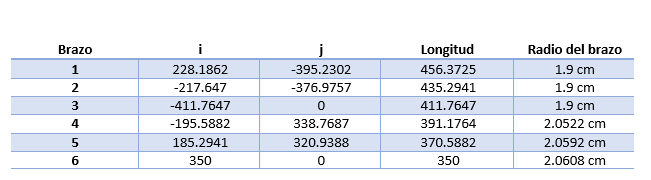

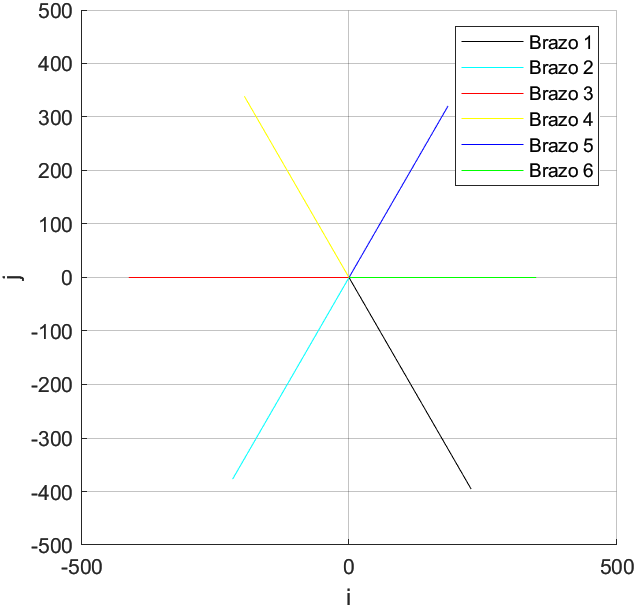

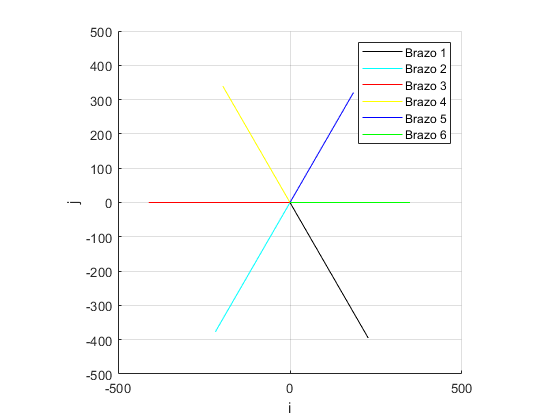

hold on;
% Brazo 1, 2, 3, 4, 5y 6
l1 = line([0, i_1], [0, j_1], 'color', 'black');          % 1
l2 = line([0, i_2], [0, j_2], 'color', 'cyan');      % 2
l3 = line([0, i_3], [0, j_3], 'color', 'red');     % 3
l4 = line([0, i_4], [0, j_4], 'color', 'yellow');         % 4
l5 = line([0, i_5], [0, j_5], 'color', 'blue');   % 5
l6 = line([0, i_6], [0, j_6], 'color', 'green');    % 6
legend([l1, l2, l3, l4, l5, l6],["Brazo 1", "Brazo 2", "Brazo 3", "Brazo 4", "Brazo 5", "Brazo 6", ])

%%%%%%%%%%             Configuration of figure (plot)             %%%%%%%%%%
% Configure cartesian plot
xlim(xlimCfg);
ylim(ylimCfg);
xlabel(xlab);
ylabel(ylab);
zlabel(zlab);
grid on;
pbaspect(aspect);
hold off;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%